# z-próba (1-mintás)

Normális eloszlást feltételezünk, ha n<30.

szigma ismert.

alpha: szignifikancia szint.

#### 1.Hipotézis: 


$$H_0: m = m_0 \\
H_1: m\neq m_0\text{ (2-oldali)} \\ \qquad m<m_0 \text{ (bal-oldali)} \\ \qquad m>m_0 \text{ (jobb-oldali)} $$


#### 2.Próbastatisztika:


$$z = \frac{\overline{x}-m_0}{\sigma}\sqrt n \sim \mathcal N (0,1), \text{ha }H_0 \text{ igaz.}$$


#### 3.P-érték: 

Annak a valószínűsége, hogy H0-t tekintve extrémebb értéket kapunk.


$$p = 2\phi (-|z|), \quad \text{(2-oldali),}\\
p = \phi (z), \quad \text{(bal-oldali),}\\
p = \phi (-z), \quad \text{(jobb-oldali),}\\
\text{ahol }\phi() \text{ a standard normális eloszlásfüggvénye.}$$


#### 4.Döntés:


$$p>\alpha: H_0 \text{ elfogadva}\\
p\leq\alpha: \text{$H_0$ elutasítva, $H_1$ elfogadva}$$
 

#### Konfidencia intervallum (CI):

$(1-\alpha)\cdot 100 \%$ kofidencia-szint mellett:


$$\mathbb{P}(m \in CI_{1-\alpha})\leq 1-\alpha$$


#### Példa

Használjuk az első oszlopát a hallgatók vizsgaeredményeinek.

load examgrades
x = grades(:,1);

Teszteljük azt a null-hipotézist, hogy a vizsgaeredmények normális eloszlásból származnak `m = 75 várható értékkel és` `sigma = 10 szórással`.

[h,p,ci,zval] = ztest(x,75,10)

h = 0

p = 0.9927

ci =    73.2191
   76.7975


zval = 0.0091

Vizsgáljuk meg, hogy a várható érték szignifikánsan nagyobb-e 65-nél.

[h,~,~,zval] = ztest(x,65,10,"Tail","right")

h = 1

zval = 10.9636

Ábrázoljuk a standard normális sűrűségfüggvényt, a próbastatisztikát és a kiritikus éréket 95% konfidencia szint mellett.

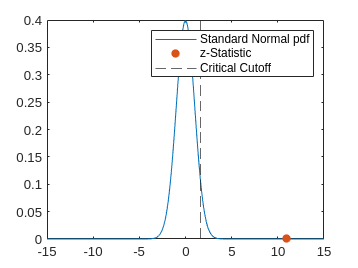

k = linspace(-15,15,300);
y = normpdf(k);
zvalpdf = normpdf(zval);
zcrit = norminv(0.95);

plot(k,y);
hold on
scatter(zval,zvalpdf,"filled")
xline(zcrit,"--")
legend(["Standard Normal pdf","z-Statistic", ...
    "Critical Cutoff"])
hold off

# t-próba (1-mintás)

sigma ismeretlen.

Eltérések a z-próbától:

#### 2.Próbastatisztika:


$$t = \frac{\overline{x}-m_0}{s^*}\sqrt n \sim t_{n-1}, \text{ ha $H_0$ igaz.}$$


#### 3.P-érték:

Használjuk a $t_{n-1}$ eloszlás eloszlásfüggvényét.

#### Példa

A napi energia bevitele (kJ) 11 nőnek az alábbi volt:

daily_intake = [5260,5470,5640,6180,6390,6515,6805,7515,7515,8230,8770]

daily_intake =         5260        5470        5640        6180        6390        6515        6805        7515        7515        8230        8770


mean(daily_intake)

ans = 6.7536e+03

std(daily_intake)

ans = 1.1421e+03

Teszteljük azt a hipotézist, hogy a nők átlagos energia bevitele 7725 kJ.

h = ttest(daily_intake,7725)

h = 1

Készítsünk egy 99%-os konfidencia intervallumot.

[~,~,ci] = ttest(daily_intake,7725,"Alpha",0.01)

ci = 1.0e+03 *

    5.6623    7.8450


# t-test (2-sample)

Röviddel azután, hogy Ausztráliában hivatalosan bevezették a metrikus hosszmértékegységeket, egy 44 diákból álló csoport mindegyikét megkérték, hogy méterben (meter) mérve tippelje meg az előadóterem szélességét, amelyben ültek. Egy másik, ugyanabban az előadóban tartózkodó 69 diákból álló csoportot arra kértek, hogy tippeljék meg a szélességet lábban (feet). A fő kérdés az, hogy a lábban és méterben kifejezett becslés eltérő eredményt ad-e.

Olvassuk be a 'roomwidth.csv' fájlt.

data = readtable('roomwidth.csv');

Váltsuk át az összes tippet láb (feet) mértékegységbe, ha 1 meter = 3.28 feet.

width = data.width;
unit = categorical(data.unit);
wfeet = width(unit == 'feet');
wmeter = width(unit == 'metres')*3.28; 

Hasonlítsuk össze a tippeket boxplot segítségével.

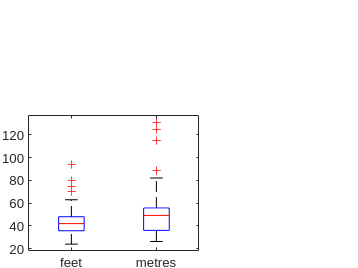

boxplot([wmeter; wfeet], unit)

Ugyanúgy tippeltek a diákok méterben mint lábban? (alpha=0.05) 

[h,p] = ttest2(wfeet, wmeter)

h = 1

p = 0.0102

#### Feladat.

Miután a diákok megbecsülték az előadóterem szélességét, a terem szélességét pontosan megmérték, és 13,1 méternek (43,0 lábnak) találták. Használja ezt a kiegészítő információt annak meghatározására, hogy a kétféle becslés közül melyik volt pontosabb (azaz melyiknek magasabb a p-értéke).

%

# t-próba (páros)

load examgrades
x = grades(:,1);
y = grades(:,2);

Teszteljük azt a null-hipotézist, hogy az első dolgozat hasonló nehézségű volt mint a második dolgozat.

[h,p] = ttest(x,y)

h = 0

p = 0.9805